# **ACM/IDS 104 - Problem Set 3 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

## **Problem 3 (10 points) The K-Means Algorithm for Clustering**

In this problem, we will be implementing the K-Means Algorithm for clustering vectors in $\mathbb{R}^2$. To start, let us load and visualize our dataset.

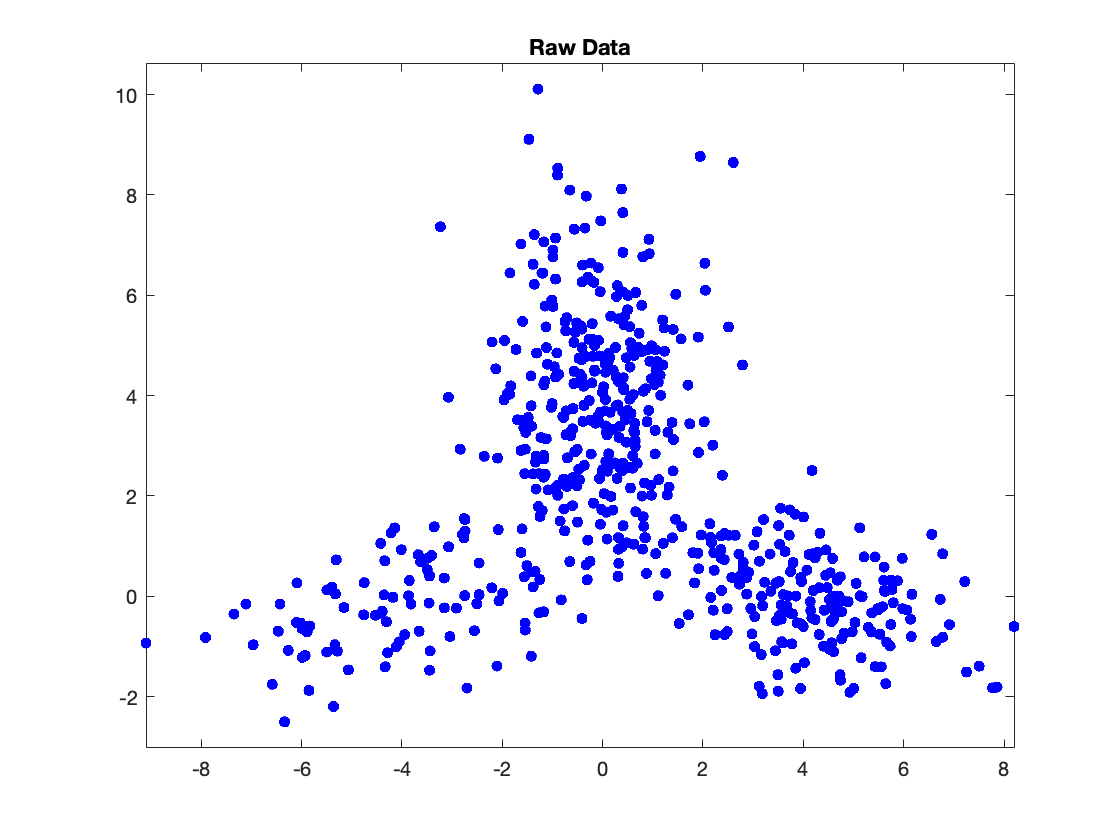

load clustering_data.mat
figure;
plot(x(:,1),x(:,2),'.b','MarkerSize',15);
title("Raw Data")
axis equal;

rng(2016); % for reproducibility

## **Part (a) The Algorithm**

In this part, we will implement the algorithm for $K=3$, which seems to be a reasonable number of clusters for this dataset. Show the clusters after the 1st, 5th, 10th and last iteration. This will illustrate the cluster evolution as the algorithm runs. $\texttt{subplot()}$ is very useful here.

To further aid our understanding of the algorithm, we will be keeping track of a few things:

- Keep track of the evolution of the representatives for each cluster. You can do so by updating the variable $\texttt{z}$ after each iteration.

- Keep track of the objective function value at each iteration.

Once you are done implementing the algorithm, feel free to change the value of $\texttt{K}$ and see how the clusterings are altered.

%{
Some useful setup done for you
%}
K = 3; % number of clusters
n = length(x); % number of vectors
c = zeros(n, 1); % clustering : c(i) is the cluster number for vector x(i, :)
previous_cluster = c;
iter = 0; % iteration number
z = datasample(x, K); % initial representatives
iter_num = 1;
objective_func = [];
plotpos = 1;


reps_history = 1×3 cell array
    {[-0.9896 6.7665]}    {[-0.3253 7.9762]}    {[-0.5055 5.3627]}


%keeps track of how the representatives change
reps_history = {z(1,:), z(2,:), z(3,:)}

colors = 1×5 string array
    ".b"    ".g"    ".r"    ".m"    ".c"


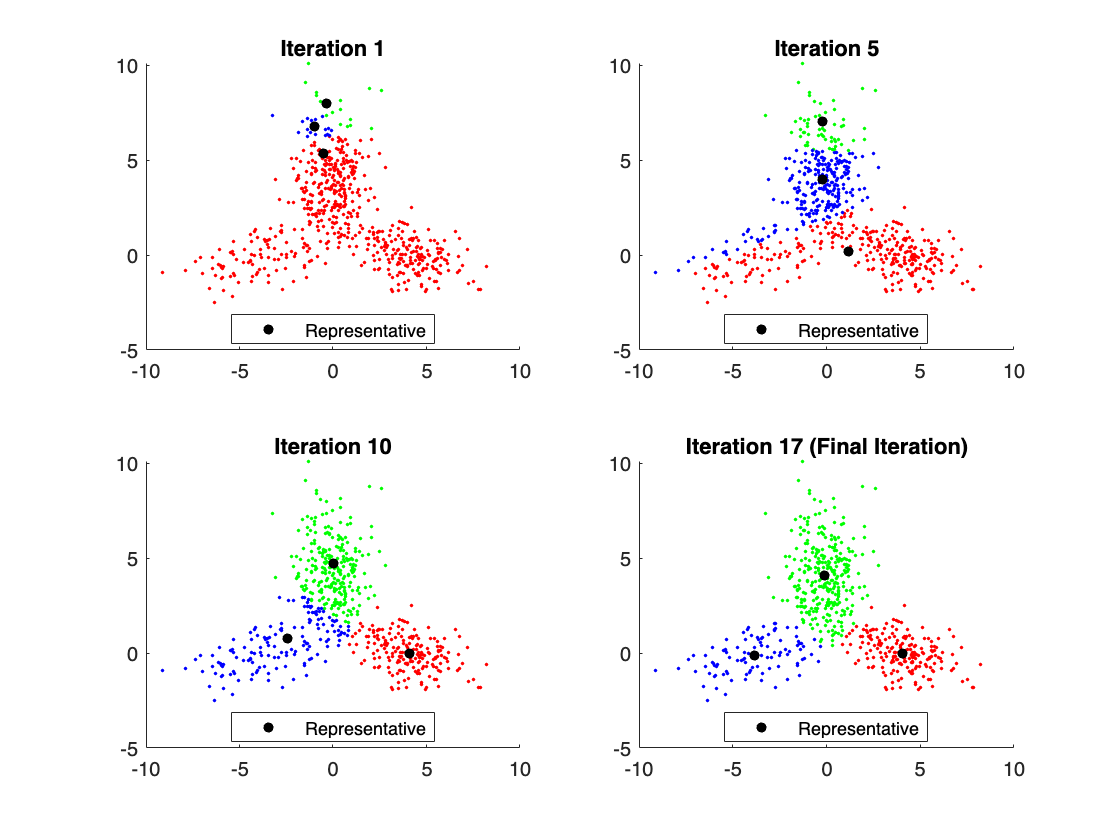

%colors and style for each cluster (assumes a max of five cluster, hence only 5 colors)
colors = [".b", ".g", ".r", ".m", ".c"]
while true
    %{ 
    Step 1: Partitioning into clusters given our initial representatives
    %}

    % sum of distances between each vector and its representative divided by n is diffs
    diffs = 0;
    for idx = 1:n
        % calculating distance between initial representatives
        % and vector in dataset
        dists = zeros(1, K);
        for rep = 1:K
            dists(rep) = norm(x(idx, :) - z(rep, :));
        end
        [M, I] = min(dists);
        c(idx, 1) = I;

        diffs = diffs + (1/n) * (norm(x(idx, :) - z(I, :)))^2;
    end

    %plot clusters
    if iter_num == 1 || iter_num == 5 || iter_num == 10
        subplot(2,2, plotpos);
        hold on
        for idx = 1:n
           cluster_num = c(idx);
           plot(x(idx, 1), x(idx, 2),colors(cluster_num),'MarkerSize',5);
           
        end
        h = plot(z(:,1), z(:,2),".k",'MarkerSize',15, 'DisplayName','Representative');
        legend(h, "Representative", "location", "best");
        title(compose("Iteration %d", iter_num))
        hold off
        plotpos = plotpos + 1;

    end

    %{
    Increment the iteration number
    Update the objective function
    %}
    objective_func = [objective_func diffs];

    %update representatives
    reps = zeros(K, 2); %used to update representatives
    for idx = 1:n
        cluster_num = c(idx);
        reps(cluster_num, :) = reps(cluster_num, :) + x(idx, :);
    end
    for i = 1:K
        nk = sum(c(:, 1) == i);
        reps(i, :) = (1/nk) * reps(i, :);
    end 
    z = reps;

    for i = 1:K
        reps_history{i} = [ reps_history{i}; z(i, :)];
    end

    %{
    Iterate until convergence:
    %}
    if isequal(previous_cluster, c)
        subplot(2,2, plotpos);
        hold on
        for idx = 1:n
           cluster_num = c(idx);
           plot(x(idx, 1), x(idx, 2),colors(cluster_num),'MarkerSize',5);
        end
        h = plot(z(:,1), z(:,2),".k",'MarkerSize',15, 'DisplayName','Representative');
        legend(h, "Representative", "location", "best");
        title(compose("Iteration %d (Final Iteration)", iter_num))
        hold off
        break
    end
    previous_cluster = c;
    iter_num = iter_num + 1;


end

%{
Plotting
%}

## **Part (b) Evolution of Representatives**

Now, let us see the dynamics of the representatives. Plot the original (raw) data and the trajectories of the cluster representatives in one figure. $\texttt{squeeze()}$ might be useful here.

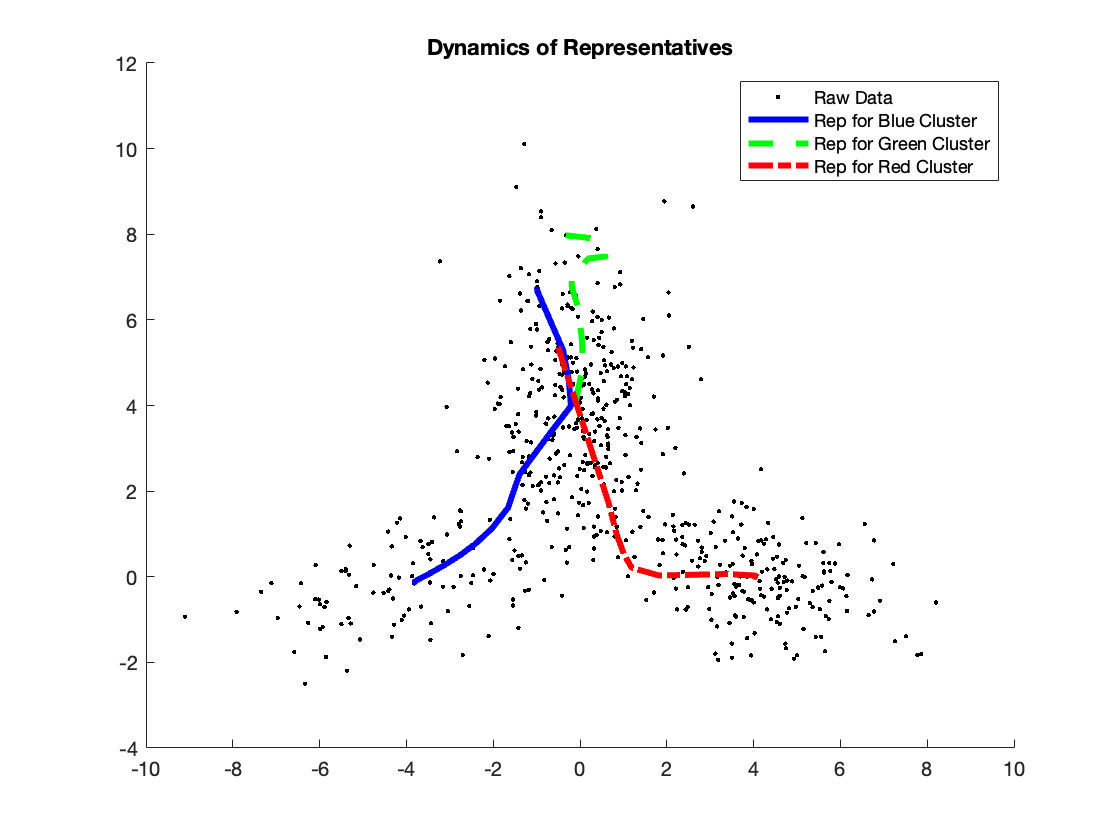

figure;
hold on
plot(x(:,1),x(:,2),'.k','MarkerSize',5, "DisplayName", "Raw Data");
plot(reps_history{1}(:,1),reps_history{1}(:,2),'-b','MarkerSize',15, "LineWidth", 3, "DisplayName", "Rep for Blue Cluster");
plot(reps_history{2}(:,1),reps_history{2}(:,2),'--g','MarkerSize',15, "LineWidth", 3, "DisplayName", "Rep for Green Cluster");
plot(reps_history{3}(:,1),reps_history{3}(:,2),'-.r','MarkerSize',15, "LineWidth", 3, "DisplayName", "Rep for Red Cluster");
hold off
legend("location", "best")
title("Dynamics of Representatives")

## **Part (c) Objective Function**

Plot the values of the objective function against the iteration number. Does the trend match what we expect? Report the minimum value of the objective function using $\texttt{disp()}$.

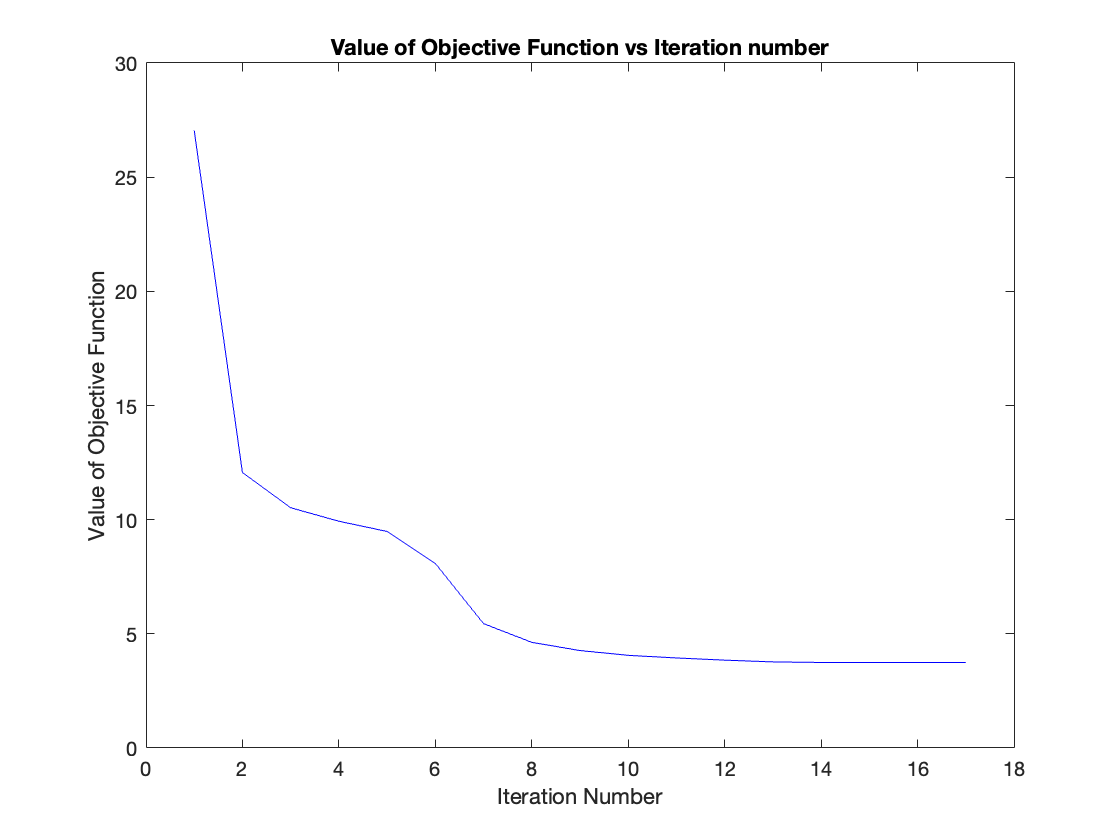

figure;
plot(1 : iter_num, objective_func(1, :),'-b','MarkerSize',10);
title("Value of Objective Function vs Iteration number")
xlabel("Iteration Number")
ylabel("Value of Objective Function")

[M,I] = min(objective_func)

M = 3.7420

I = 17

disp(M)

    3.7420



## **Part (d) Comparing with **$\texttt{kmeans()}$

The K-means algorithm is a very popular clustering algorithm and it is often used in various applications. As such, it is implemented in most numerical software packages. In MATLAB, it exists as the built-in function $\texttt{kmeans()}$. In the simplest form, $\texttt{idx = kmeans(X, k)}$ performs K-means clustering to partition the rows in the data matrix $\texttt{X}$ into $\texttt{k}$ clusters, and returns a vector $\texttt{idx}$ containing cluster indices for each row. To compare your implementation with the built-in one, plot the clustering your obtained in (a) and the clustering obtained by using $\texttt{kmeans()}$.

idx = kmeans(x, K)

idx =      1
     1
     1
     1
     1
     1
     1
     1
     3
     3


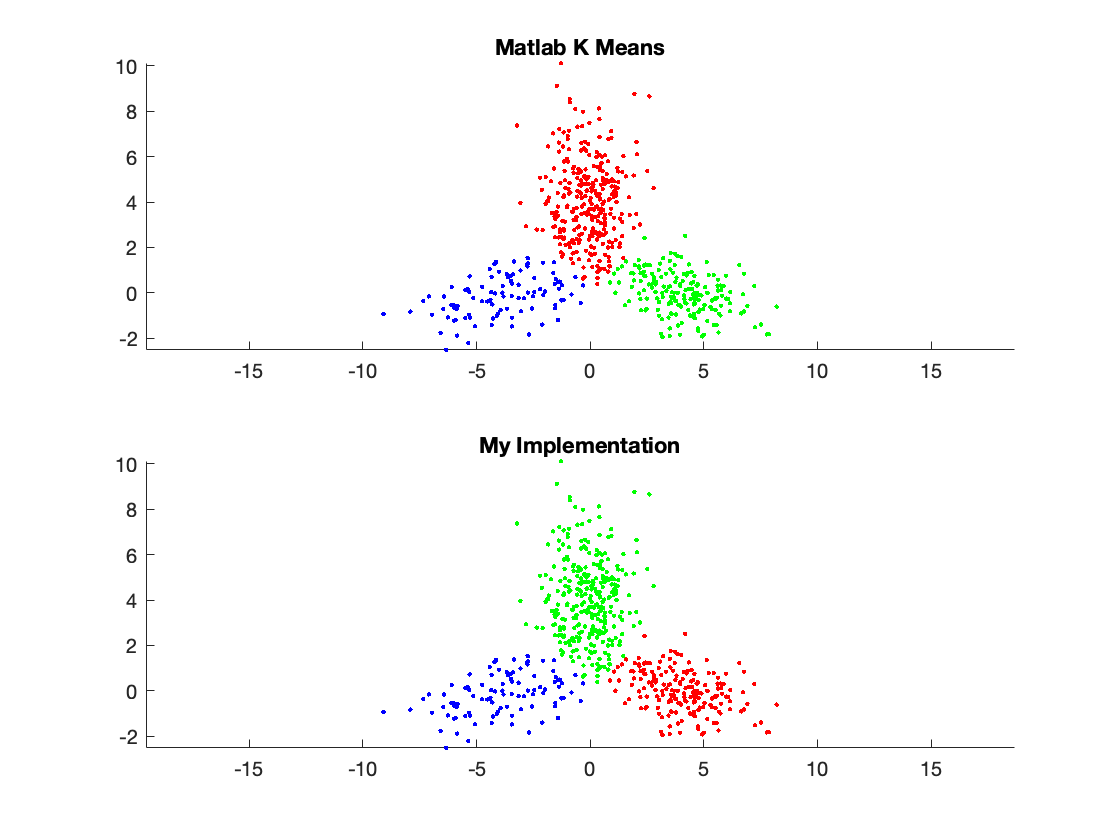

figure;
subplot(2,1, 1);
hold on
for i = 1:n
   cluster_num = idx(i);
   plot(x(i, 1), x(i, 2),colors(cluster_num),'MarkerSize',5);
end
%legend(h, "Representative", "location", "best");
title("Matlab K Means")
axis equal;
hold off
subplot(2,1, 2);
hold on
for i = 1:n
   cluster_num = c(i);
   plot(x(i, 1), x(i, 2),colors(cluster_num),'MarkerSize',5);
end
hold off
title("My Implementation")
axis equal;

## **Problem 5 (10 points) Gram Matrices for Text Classification**

Gram matrices are used in many different applications. Here is a simple example of application to classification of text documents. Suppose we have a collection of $n$ text documents and we want to measure similarity between them. First, we predefine a list of words (the "dictionary'') $w_1,w_2,w_3,\cdots , w_m$ appearing in the documents. Then, for each text $i$ we construct a vector $x_i\in\mathbb{R}^m$ whose $j^{\text{th}}$ component is the number of times the word $w_j$ appears in the text. This way, each text is represented as a vector in $\mathbb{R}^m$. This representation is often referred to as the "bag of words" representation. 

Let $\langle\cdot,\cdot\rangle$ be the usual dot product in $\mathbb{R}^m$ and $\|\cdot\|$ be the Euclidean norm. Let us normalize all vectors $z_i = \frac{x_i}{\|x_i\|}$ and define:


$$Z = [z_1\cdots z_n]\in\mathbb{M}_{m\times n}$$


Let $G$ be the Gram matrix associated with $z_1\cdots z_n$:


$$G = Z^TZ\in \mathbb{M}_{n\times n}$$


Since all $z_i$ are unit vectors:


$$G_{ij}=z_i^Tz_j=\|z_i\|\|z_j\|\cos\theta_{ij}=\cos\theta_{ij}$$


where $\theta_{ij}$is the angle between $z_i$ and $z_j$, which of course is the same as the angle between $x_i$ and $x_j$. This is widely use as a *measure of similarity* between documents. Hence, the more similar two texts $i$ and $j$ are, the closer $G_{ij}$ is to 1.

Now, let us apply this method to real texts. The task is to compare the text of the US Constitution ([found here](https://www.constituteproject.org/constitution/United_States_of_America_1992)) with the Wikipedia pages of Bernie Sanders, Hillary Clinton, Donald Trump, Ted Cruz, and John Kasich, and to find the page which is "closest" to the Constitution.

## Part (a) Setup

To start, we will define a list of $m=10$ words. To find the most "relevant words", copy the text of the Constitution and paste it into a word-cloud generator ([such as this one](http://worditout.com/word-cloud/make-a-new-one)). High frequency words appear large and we can form the dictionary from these words. Note that common sense is needed: words like "amendment'' and "section'' would appear large, but it makes no sense to include them into the dictionary. Also, it makes sense to include "United States'' as a single "word'', not two separate words, etc. But you are free to chose your own dictionary. In the code box below, please fill out the dictionary with your chosen words.


%Dictionary:
%    1) states
%    2) any  
%    3) all
%    4) law 
%    5) person 
%    6) house 
%    7) other 
%    8) number 
%    9) each 
%    10) one     

## Part (b) Fun

With your specified dictionary, let us see which Wikipedia page is closest. First, construct $n=6$ vectors (as specified above), one for each Wikipedia page and one for the Constitution. No need to get fancy here; just go to the related page and search for the number of occureneces of the words in your dictionary. Put all your results in a column vector for each candidate:

%{
Report your results here
%}
sanders = [68 14 50 26 9 50 31 9 5 30];
clinton = [59 15 51 44 19 63 40 9 2 36];
trump = [90 26 101 66 42 71 46 15 6 35];
cruz = [97 13 52 83 19 22 26 3 4 25];
kasich = [29 8 34 36 7 53 21 5 1 18];
constitution =[132 80 43 39 34 34 31 26 26 25];


Z =

     []



vecs = {sanders, clinton, trump, cruz, kasich, constitution};
Z = []
%{
Normalize your vectors
%}
for i = 1:6
    vecs{i} = (1/norm(vecs{i})) * vecs{i}

vecs = 1×6 cell array
    {[0.6071 0.1250 0.4464 0.2321 0.0804 0.4464 0.2768 0.0804 0.0446 0.2679]}    {[59 15 51 44 19 63 40 9 2 36]}    {[90 26 101 66 42 71 46 15 6 35]}    {[97 13 52 83 19 22 26 3 4 25]}    {[29 8 34 36 7 53 21 5 1 18]}    {[132 80 43 39 34 34 31 26 26 25]}


Z =     0.6071    0.1250    0.4464    0.2321    0.0804    0.4464    0.2768    0.0804    0.0446    0.2679


vecs = 1×6 cell array
    {[0.6071 0.1250 0.4464 0.2321 0.0804 0.4464 0.2768 0.0804 0.0446 0.2679]}    {[0.4731 0.1203 0.4089 0.3528 0.1523 0.5051 0.3207 0.0722 0.0160 0.2887]}    {[90 26 101 66 42 71 46 15 6 35]}    {[97 13 52 83 19 22 26 3 4 25]}    {[29 8 34 36 7 53 21 5 1 18]}    {[132 80 43 39 34 34 31 26 26 25]}


Z =     0.6071    0.1250    0.4464    0.2321    0.0804    0.4464    0.2768    0.0804    0.0446    0.2679
    0.4731    0.1203    0.4089    0.3528    0.1523    0.5051    0.3207    0.0722    0.0160    0.2887


vecs = 1×6 cell array
    {[0.6071 0.1250 0.4464 0.2321 0.0804 0.4464 0.2768 0.0804 0.0446 0.2679]}    {[0.4731 0.1203 0.4089 0.3528 0.1523 0.5051 0.3207 0.0722 0.0160 0.2887]}    {[0.4900 0.1415 0.5499 0.3593 0.2287 0.3865 0.2504 0.0817 0.0327 0.1905]}    {[97 13 52 83 19 22 26 3 4 25]}    {[29 8 34 36 7 53 21 5 1 18]}    {[132 80 43 39 34 34 31 26 26 25]}


Z =     0.6071    0.1250    0.4464    0.2321    0.0804    0.4464    0.2768    0.0804    0.0446    0.2679
    0.4731    0.1203    0.4089    0.3528    0.1523    0.5051    0.3207    0.0722    0.0160    0.2887
    0.4900    0.1415    0.5499    0.3593    0.2287    0.3865    0.2504    0.0817    0.0327    0.1905


vecs = 1×6 cell array
    {[0.6071 0.1250 0.4464 0.2321 0.0804 0.4464 0.2768 0.0804 0.0446 0.2679]}    {[0.4731 0.1203 0.4089 0.3528 0.1523 0.5051 0.3207 0.0722 0.0160 0.2887]}    {[0.4900 0.1415 0.5499 0.3593 0.2287 0.3865 0.2504 0.0817 0.0327 0.1905]}    {[0.6640 0.0890 0.3559 0.5681 0.1301 0.1506 0.1780 0.0205 0.0274 0.1711]}    {[29 8 34 36 7 53 21 5 1 18]}    {[132 80 43 39 34 34 31 26 26 25]}


Z =     0.6071    0.1250    0.4464    0.2321    0.0804    0.4464    0.2768    0.0804    0.0446    0.2679
    0.4731    0.1203    0.4089    0.3528    0.1523    0.5051    0.3207    0.0722    0.0160    0.2887
    0.4900    0.1415    0.5499    0.3593    0.2287    0.3865    0.2504    0.0817    0.0327    0.1905
    0.6640    0.0890    0.3559    0.5681    0.1301    0.1506    0.1780    0.0205    0.0274    0.1711


vecs = 1×6 cell array
    {[0.6071 0.1250 0.4464 0.2321 0.0804 0.4464 0.2768 0.0804 0.0446 0.2679]}    {[0.4731 0.1203 0.4089 0.3528 0.1523 0.5051 0.3207 0.0722 0.0160 0.2887]}    {[0.4900 0.1415 0.5499 0.3593 0.2287 0.3865 0.2504 0.0817 0.0327 0.1905]}    {[0.6640 0.0890 0.3559 0.5681 0.1301 0.1506 0.1780 0.0205 0.0274 0.1711]}    {[0.3465 0.0956 0.4062 0.4301 0.0836 0.6332 0.2509 0.0597 0.0119 0.2150]}    {[132 80 43 39 34 34 31 26 26 25]}


Z =     0.6071    0.1250    0.4464    0.2321    0.0804    0.4464    0.2768    0.0804    0.0446    0.2679
    0.4731    0.1203    0.4089    0.3528    0.1523    0.5051    0.3207    0.0722    0.0160    0.2887
    0.4900    0.1415    0.5499    0.3593    0.2287    0.3865    0.2504    0.0817    0.0327    0.1905
    0.6640    0.0890    0.3559    0.5681    0.1301    0.1506    0.1780    0.0205    0.0274    0.1711
    0.3465    0.0956    0.4062    0.4301    0.0836    0.6332    0.2509    0.0597    0.0119    0.2150


vecs = 1×6 cell array
    {[0.6071 0.1250 0.4464 0.2321 0.0804 0.4464 0.2768 0.0804 0.0446 0.2679]}    {[0.4731 0.1203 0.4089 0.3528 0.1523 0.5051 0.3207 0.0722 0.0160 0.2887]}    {[0.4900 0.1415 0.5499 0.3593 0.2287 0.3865 0.2504 0.0817 0.0327 0.1905]}    {[0.6640 0.0890 0.3559 0.5681 0.1301 0.1506 0.1780 0.0205 0.0274 0.1711]}    {[0.3465 0.0956 0.4062 0.4301 0.0836 0.6332 0.2509 0.0597 0.0119 0.2150]}    {[0.7328 0.4441 0.2387 0.2165 0.1888 0.1888 0.1721 0.1443 0.1443 0.1388]}


Z =     0.6071    0.1250    0.4464    0.2321    0.0804    0.4464    0.2768    0.0804    0.0446    0.2679
    0.4731    0.1203    0.4089    0.3528    0.1523    0.5051    0.3207    0.0722    0.0160    0.2887
    0.4900    0.1415    0.5499    0.3593    0.2287    0.3865    0.2504    0.0817    0.0327    0.1905
    0.6640    0.0890    0.3559    0.5681    0.1301    0.1506    0.1780    0.0205    0.0274    0.1711
    0.3465    0.0956    0.4062    0.4301    0.0836    0.6332    0.2509    0.0597    0.0119    0.2150
    0.7328    0.4441    0.2387    0.2165    0.1888    0.1888    0.1721    0.1443    0.1443    0.1388


    Z = [Z ; vecs{i}]

Z =     0.6071    0.4731    0.4900    0.6640    0.3465    0.7328
    0.1250    0.1203    0.1415    0.0890    0.0956    0.4441
    0.4464    0.4089    0.5499    0.3559    0.4062    0.2387
    0.2321    0.3528    0.3593    0.5681    0.4301    0.2165
    0.0804    0.1523    0.2287    0.1301    0.0836    0.1888
    0.4464    0.5051    0.3865    0.1506    0.6332    0.1888
    0.2768    0.3207    0.2504    0.1780    0.2509    0.1721
    0.0804    0.0722    0.0817    0.0205    0.0597    0.1443
    0.0446    0.0160    0.0327    0.0274    0.0119    0.1443
    0.2679    0.2887    0.1905    0.1711    0.2150    0.1388


end
Z = Z'


%{
Construct the Gram matrix G as discussed

G =     1.0000    0.9771    0.9634    0.8807    0.9253    0.8596
    0.9771    1.0000    0.9723    0.8751    0.9729    0.8062
    0.9634    0.9723    1.0000    0.9055    0.9341    0.8332
    0.8807    0.8751    0.9055    1.0000    0.8167    0.8484
    0.9253    0.9729    0.9341    0.8167    1.0000    0.7051
    0.8596    0.8062    0.8332    0.8484    0.7051    1.0000


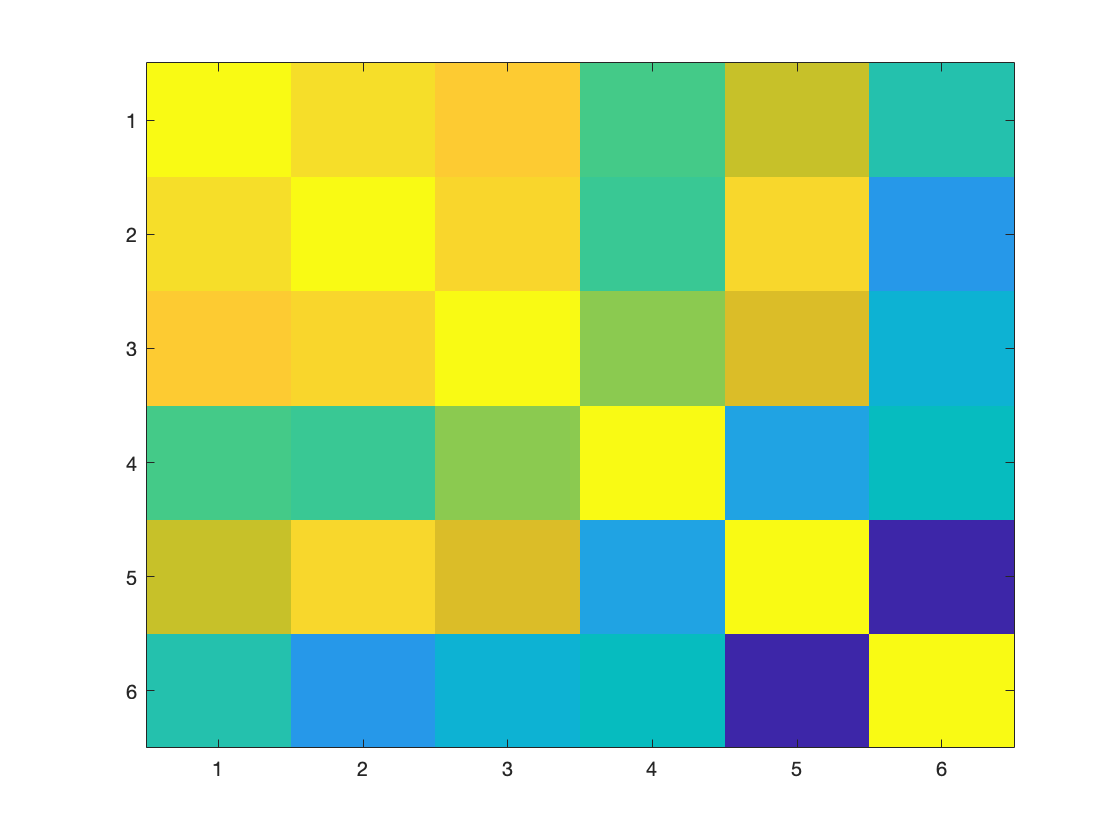

%}
G = Z' * Z

%{
You can visualize G by uncommenting the following lines of code
%}

figure;


angles =

     []



imagesc(G);
angles = []
for i = 1:5
    cosine = dot(Z(:,i), Z(:,6));

angles = 0.5363

angles =     0.5363    0.6331


angles =     0.5363    0.6331    0.5860


angles =     0.5363    0.6331    0.5860    0.5579


angles =     0.5363    0.6331    0.5860    0.5579    0.7882


    angles = [angles acos(cosine)]
end

[M, I] = min(angles);

%{
Find the page closest to the Constitution text and report your
answer using disp()
%}

Bernie Sanders Page is the closest to the Constitution


pages = ["Bernie Sanders", "Hillary Clinton", "Donald Trump", "Ted Cruz", "John Kasich"];

    0.6071
    0.1250
    0.4464
    0.2321
    0.0804
    0.4464
    0.2768
    0.0804
    0.0446
    0.2679



disp(append(pages(I,1), " Page is the closest to the Constitution"));
disp(Z(:,I));

Submit the obtained result to the corresponding piazza poll. Remember: this is not about your political preferences, it is about your data analysis :)